# **Section 4: Plotting Data in MATLAB**

**“What is the best way for me to visually communicate my data in MATLAB?”**

In this section we will develop familiarity with plots in MATLAB. Cover how to create, resize, label, and adjust plots to desired specifications.

## Maps

You may have heard there is no way to truly correct way to represent our Earth on a flat image. It is impossible to unwrap the spherical dimensions of the globe to perfectly portray the layout and shapes of our globe on a 2D surface. This has posed a fundamental challenge from the inception of their tradition. Mapmakers have had to decide what information to preserve and what information to distort to communicate the important information their maps need to convey. As a result, there are many “projections” or techniques of flattening the globe that have proven useful.

The Mercator projection is a popular map style for use in navigation. It represents lines of straight travel on a constant course, which proved useful for planning trips across the sea.  To convey course properly, the size of landmasses is greatly distorted. This is why Greenland is often mistaken for being over 500 times larger than it really is.

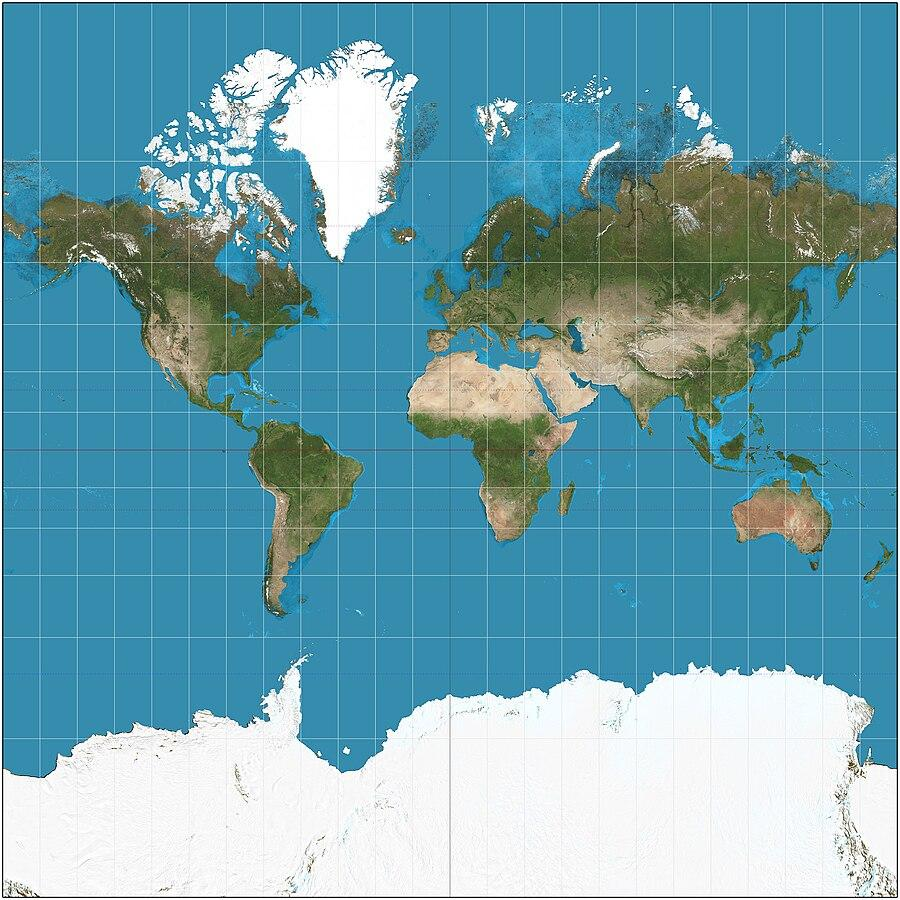

*Image: Daniel R. Strebe 17/12/2011 *[*CC BY-SA 3.0*](https://creativecommons.org/licenses/by-sa/3.0/)

Even the positioning of landmasses is a result of decisions made by the mapmakers. Europe might not have been positioned in the top-center if the mapmakers were raised somewhere else. There is no up or down or left or right in space, and these decisions do not represent objective truth.

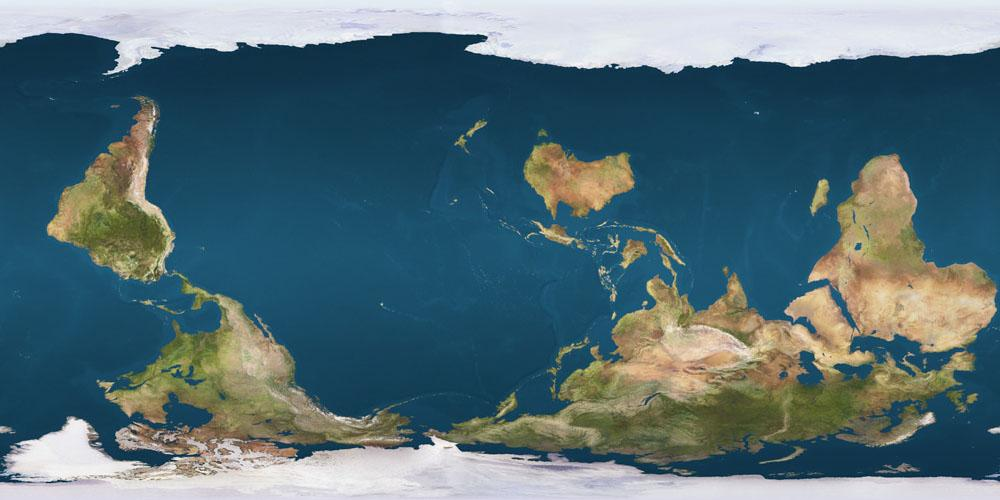

When we communicate data, we are -in a way- ‘mapmakers’, charting informational territory and placing emphasis on aspects of data we are trying to emphasize. This comes with a lot of decision-making and utilization of different techniques. 

Now search the web for different types of maps. What do each of them emphasise or distort?

## **STEP 1: Importing your data**

In order to plot our data, first we have to be able to access it from the excel file.

clc; clear; %clean up the workspace

%remember you can right click a file in your "Files" tab to the left and
%click "Copy Path" and paste that as your filename to get the correct
%directory and find you data file

filename = "/MATLAB Drive/MATLAB - Section 04 (Student - File Share)/Data/datatest.xlsx"; %locate our data
spreadsheet = readmatrix(filename); %read our data file
disp(spreadsheet); %show off our new variable

     1    10
     2     4
     3    25
     4     6
     5    20



## STEP 2: Plotting Functions

### Simple Line graph

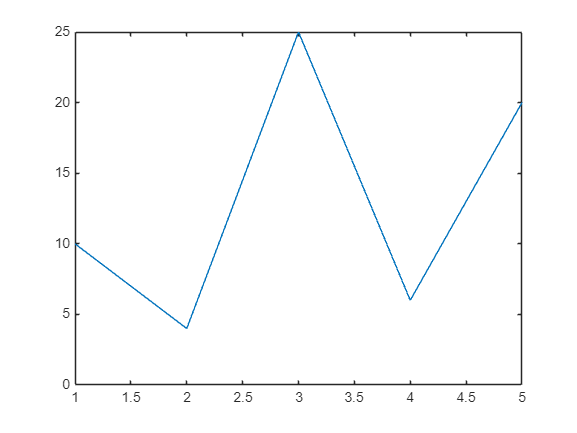

col1 = spreadsheet(:,1); %assign first column to var col1
col2 = spreadsheet(:,2); %assign second column to var col2

%plot(x,y) function used to display data
plot(col1,col2);

### Other Plot Types

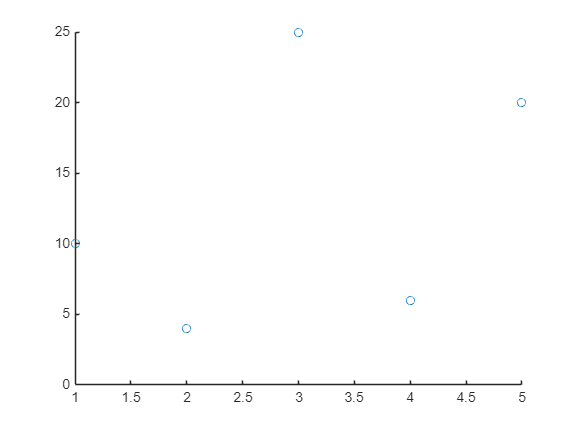

scatter(col1,col2); %scatter plot

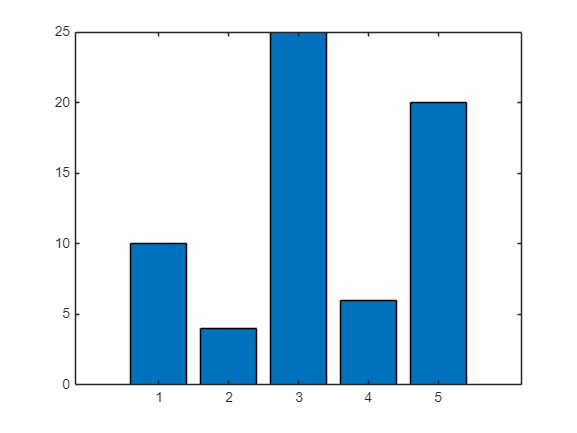

bar(col1,col2); %bar graph

## STEP 3: Lil Pump

Now let's take a look at how we can use plots in action. A few years ago, Lil Pump was the talk of the town. The question is: what is he up to now? Let's look into the current status of the once world-famous Gucci Gang artist.

### Importing Data

Use the readcell() funtion to import data from excel.

clc;clear;
data = readcell("/MATLAB Drive/MATLAB - Section 04 (Student - File Share)/Data/lilpumpdata.xlsx");
 

Take a look at the data, which colums are the most important for tracking popularity over time? ('chart_week' and 'rank_score_sum')

Rank_score_sum is an aggregate data point ranking an artists popularity with a score representing streams, downloads, radio time, etc.

Now create two arrays named 'rank' and 'date' containing the data of columns 5 and 3, respiectivley. (Hint: make sure to exclude the titles in the first row)

rank = data(2:end,5); 
date = data(2:end,3);

%combine rank and date into a 2D array
cell_array = [date, rank];
%convert from type 'cell' to type 'table'
data_table = cell2table(cell_array,'VariableNames',{'Date','Rank'});
%convert to timetable
music_timetable = table2timetable(data_table);
 

**Simple Plot**

Now we have a TimeTable containing Date and Rank information, let's try plotting this data.

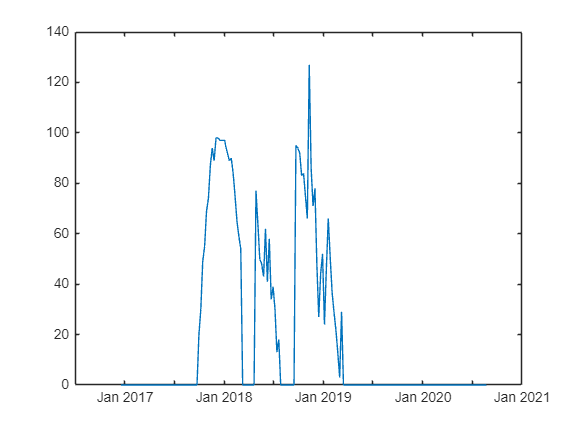

plot(music_timetable.Date,music_timetable.Rank);

This chart shows us a standardized measurement of Lil Pump's popularity over the course of a few years.

Let's zoom in and look at his rank in the charts over his first major peak in popularity.

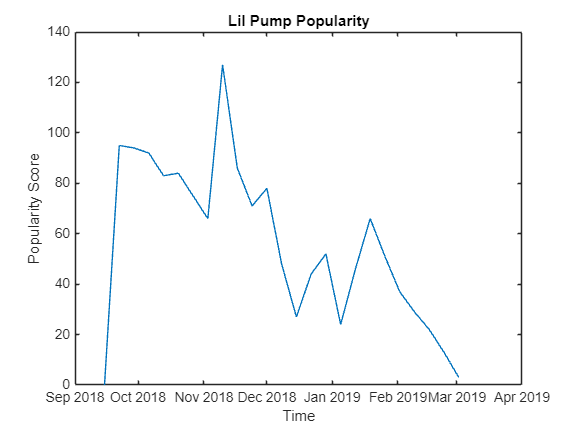

%access Date and Rank colums and select items 78 through 102 
%   (as this is where we would like to zoom)
plot(music_timetable.Date(78:102), music_timetable.Rank(78:102)); 
%lets add a title for clarity
title("Lil Pump Popularity");
%label axes
xlabel("Time");
ylabel("Popularity Score");